# Lecture 3: Digital Image Fundamentals

# Part 2: Resolution

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in both Matlab IPT *imdata* folder and *images* folder in the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture3 - Digital Image Fundamentals

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

## Effective spatial resolution

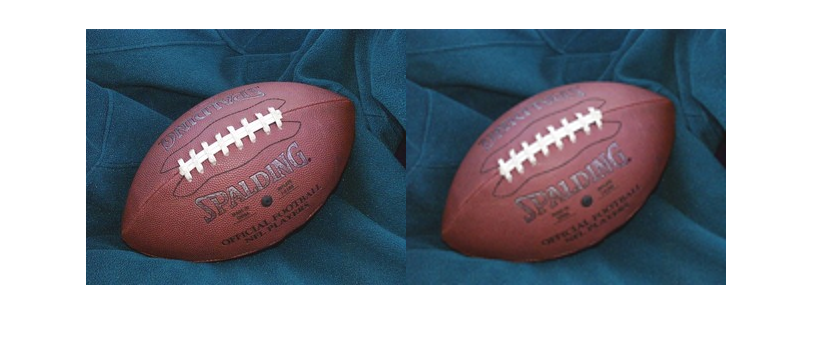

I = imread('football.jpg');
I1 = imresize(I, 0.5);
I2 = imresize(I1, 2);
imshowpair(I,I2,'montage');

## Intensity Level Resolution

I = imread('cameraman.tif');
I1 = I/64;
max(I1(:))

ans = uint8
4

I2 = I/128;
max(I2(:))

ans = uint8
2

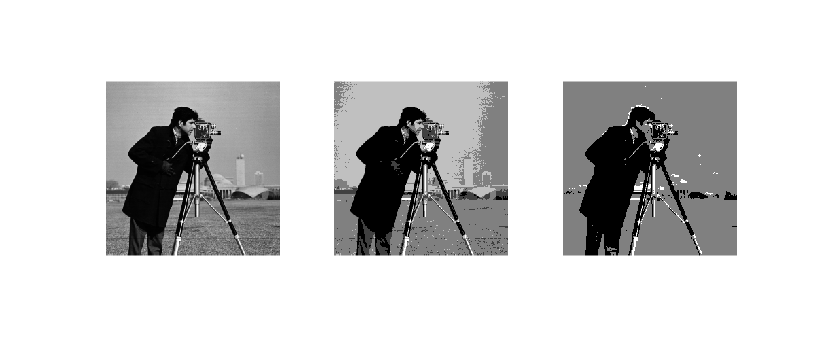

subplot(1,3,1)
imshow(I, [])
subplot(1,3,2)
imshow(I1,[])
subplot(1,3,3)
imshow(I2, [])